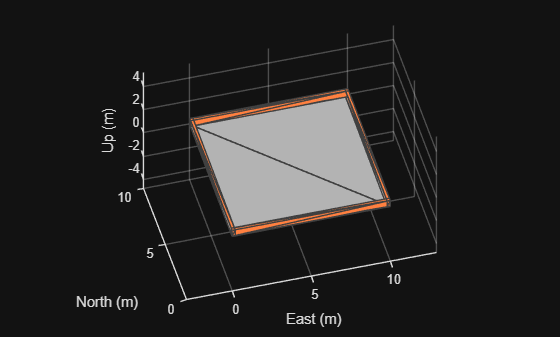

clear all;

scenario = robotScenario(UpdateRate=10);

addMesh(scenario,"Plane",Position=[5 5 0],Size=[10 10],Color=[0.7 0.7 0.7]);

addMesh(scenario,"Box",Position=[5 9.9 0.25],Size=[10 0.2 0.5],Color=[1 0.5 0.25],IsBinaryOccupied=true);
addMesh(scenario,"Box",Position=[5 0.1 0.25],Size=[10 0.2 0.5],Color=[1 0.5 0.25],IsBinaryOccupied=true);
addMesh(scenario,"Box",Position=[0.1 5 0.25],Size=[0.2 10 0.5],Color=[1 0.5 0.25],IsBinaryOccupied=true);
addMesh(scenario,"Box",Position=[9.9 5 0.25],Size=[0.2 10 0.5],Color=[1 0.5 0.25],IsBinaryOccupied=true);

show3D(scenario);
az = -15;
el = 45;
view(az, el);
grid on;

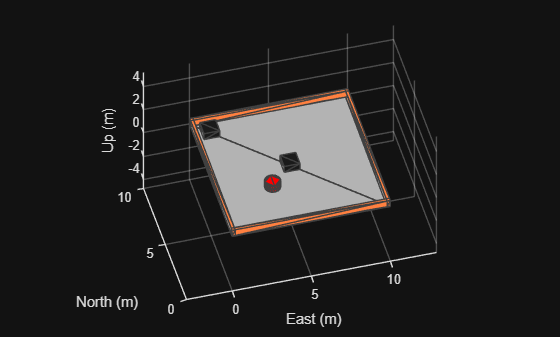

addMesh(scenario,"Box",Position=[1 9 0.25],Size=[1 1 0.5],Color=[0.1 0.1 0.1]);
addMesh(scenario,"Box",Position=[5 5 0.25],Size=[1 1 0.5],Color=[0.1 0.1 0.1]);
addMesh(scenario,"Cylinder",Position=[3.5 3.5 0.25],Size=[0.5 0.5],Color=[1 0 0]);

show3D(scenario);
view(az, el);
grid on;

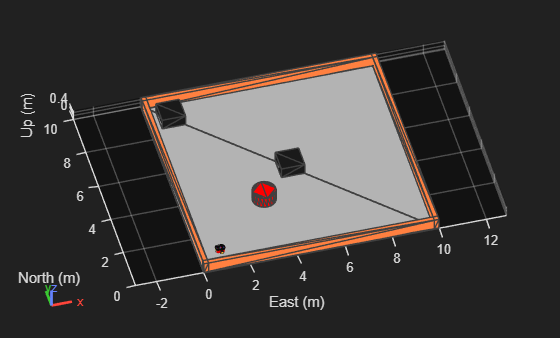

loadingPosition = [1 1];
unloadingPosition = [8 8];

[pioneerRBT,pioneerRBTInfo] = loadrobot("amrPioneer3DX");

robotA = robotPlatform("MobileRobotA",scenario,...
            RigidBodyTree=pioneerRBT,...
            InitialBasePosition=[loadingPosition,0]);

show3D(scenario);
view(az, el);
grid on;

lidarConfig = struct(angleLower=-120, angleUpper=120,...
                      angleStep=0.2, maxRange=3, updateRate=2);

lidarmodel = robotLidarPointCloudGenerator(...
                AzimuthResolution=lidarConfig.angleStep,...
                AzimuthLimits=[lidarConfig.angleLower, lidarConfig.angleUpper],...
                ElevationLimits=[0 1],...
                ElevationResolution=1,...
                MaxRange=lidarConfig.maxRange,...
                UpdateRate=lidarConfig.updateRate,...
                HasOrganizedOutput=true);

lidarA = robotSensor("LidarA", robotA, lidarmodel, MountingLocation=[0 0 0.4]);

[ax,plotFrames] = show3D(scenario);
view(az, el);
grid on;

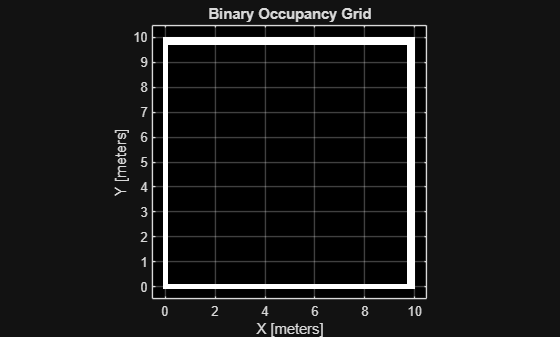

map = binaryOccupancyMap(scenario,MapHeightLimits=[0 5],...
                       GridOriginInLocal=[-0.5 -0.5], MapSize=[11 11]);


figure;
show(map);
grid on;

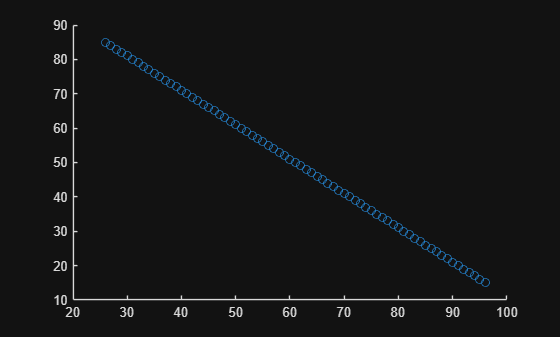

loadingGridLocation = world2grid(map,loadingPosition);
unloadingGridLocation = world2grid(map,unloadingPosition);

plannerA = plannerAStarGrid(map);
plannedGridPathA = plan(plannerA,loadingGridLocation,unloadingGridLocation);
scatter(plannedGridPathA(:,1),plannedGridPathA(:,2));

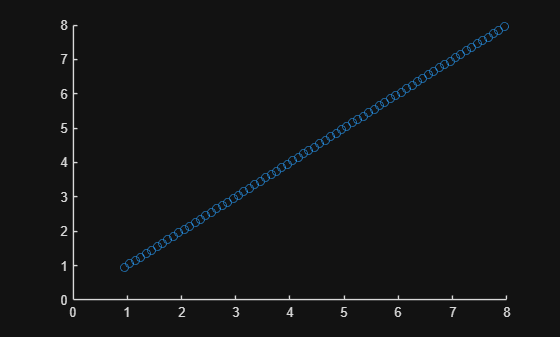

plannedWorldPathA = grid2world(map,plannedGridPathA);
scatter(plannedWorldPathA(:,1),plannedWorldPathA(:,2));

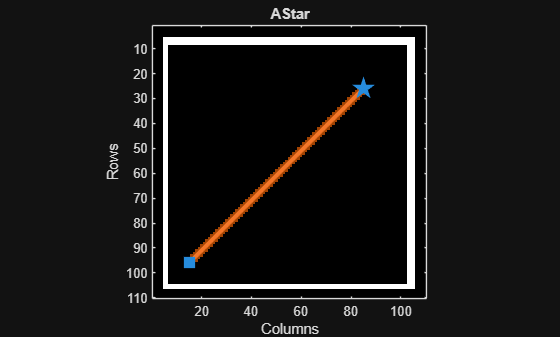

show(plannerA)

% Specify kinematic motion model for robot A.
robotDiffA = copy(pioneerRBTInfo.MobileBaseMotionModel);
robotDiffA.VehicleInputs = "VehicleSpeedHeadingRate";
robotDiffA.WheelSpeedRange = [-Inf Inf];

% Get Start and Goal Poses for robot A.
robotAStartPosition = plannedWorldPathA(1,:);
robotAGoalPosition = plannedWorldPathA(end,:);
robotAInitialOrientation = 0;
robotACurrentPose = [robotAStartPosition,robotAInitialOrientation]';

% Setup controllerPurePursuit for robot A.
controllerA = controllerPurePursuit;
controllerA.Waypoints = plannedWorldPathA;
controllerA.DesiredLinearVelocity = 0.3;
controllerA.MaxAngularVelocity = 2;
controllerA.LookaheadDistance = 0.3;

% Setup controllerVFH for robot A.
vfhA = controllerVFH;
vfhA.UseLidarScan = true;
vfhA.SafetyDistance = 0.2;

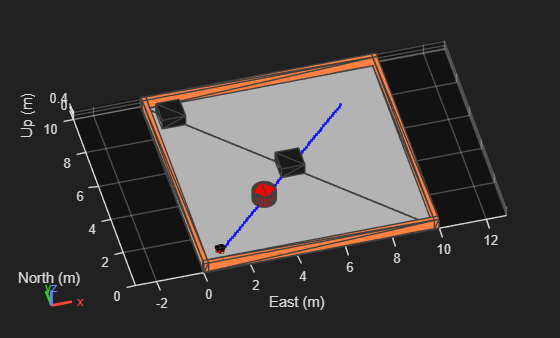

hold(ax,"on")

% Visualize planned path for robot A.
plannedPathA = plot(ax,plannedWorldPathA(:,1),plannedWorldPathA(:,2),"-bs",...
                    LineWidth=1, MarkerSize=1.5, MarkerEdgeColor="b",...
                    MarkerFaceColor=[0.5 0.5 0.5]);

hold(ax,"off")

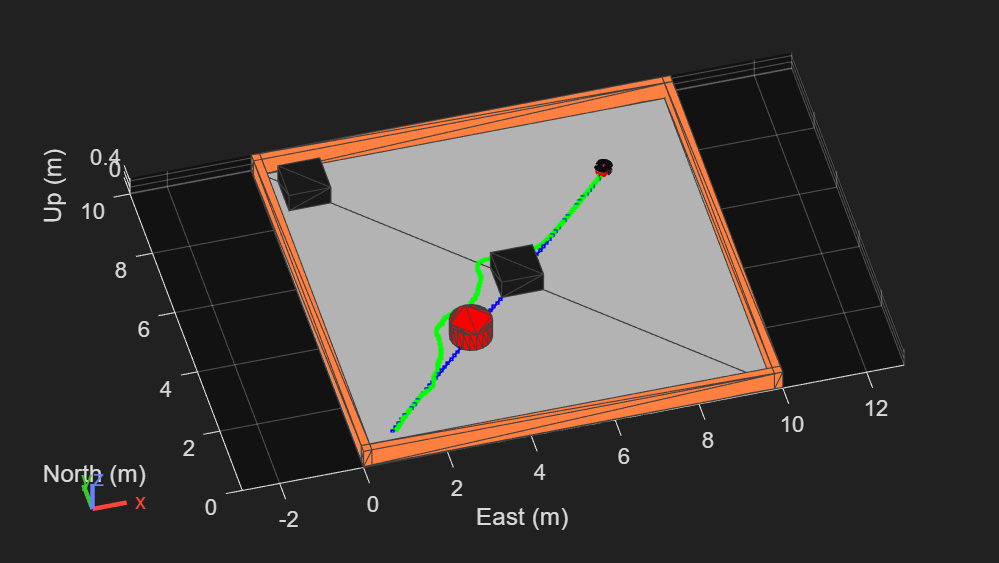

%h = figure;

setup(scenario)

robotAReached = false;
stopSimulation = false;
  
while ~stopSimulation
    
    if ~robotAReached
        [robotACurrentPose, isUpdatedA, robotAReached, pointCloudA] = ...
            exampleHelperGetCurrentPose(controllerA, robotDiffA, vfhA, lidarA, ...
                    lidarConfig, robotACurrentPose, robotAGoalPosition, robotAReached);
    end

    if robotAReached
        stopSimulation = true;
    end

    if isUpdatedA
        show3D(scenario,FastUpdate=true,Parent=ax);
        refreshdata;
        drawnow limitrate;
    end

    if ~robotAReached
        move(robotA,"base",[robotACurrentPose(1), robotACurrentPose(2), 0, ...
                            zeros(1,6), eul2quat([robotACurrentPose(3), 0,0]),...
                            zeros(1,3)]);

        hold(ax,"on");
        followedPathA = plot(ax,robotACurrentPose(1),robotACurrentPose(2),"-gs",...
                                LineWidth=1, MarkerSize=1.5,...
                                MarkerEdgeColor="g", MarkerFaceColor=[0.5 0.5 0.5]);

        %set(h, 'Position', [50 50 800 400]);
        %show(vfhA);

        hold(ax,"off");
    end

    advance(scenario);
    updateSensors(scenario);
end